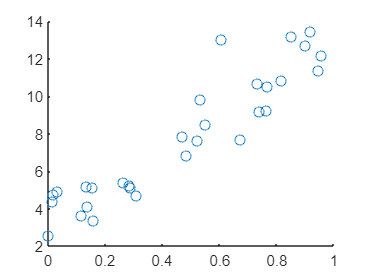

clear all
close all
addpath('Assignment 5\matlab_files')
load('EQ1_Data.mat')
scatter(data(:,1),data(:,2))

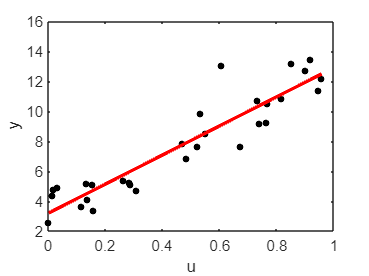

U = data(: ,1) ;
Y = data(: ,2) ;
N = numel( U ) ;
Phi = [U , ones(N ,1) ];
x = ( Phi'* Phi ) \( Phi'* Y ) ;
plot (U ,Y ,'k.', MarkerSize =12)
hold all
plot(U ,[ U , ones(N ,1) ]* x ,'r', LineWidth =2)
ylabel('y')
xlabel('u')
ylim ([2 ,16])

clear all
close all
load('EQ2_Data.mat')
U = data(: ,1) ;
Y = data(: ,2) ;
7

ans = 7

N = numel( U ) ;
eta = 5; % no. of neurons
C = -2:0.5:2;
w = 0.1;
for i = 1: eta
    R(: , i ) = RB(U , C ( i ) ) ;
end
Phi = [ ones(N ,1) , R ];
x = ( Phi'* Phi + N * w * eye ( eta +1) ) \( Phi'* Y ) ;
disp( x )

   -0.9679
   -6.8756
   -6.6905
   -3.9643
    0.3687
    5.4222



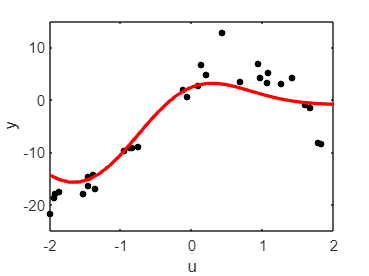

figure ()
plot(U ,Y ,'k.', MarkerSize =12)
hold all
u = linspace( -2 ,2 , N )';
for i = 1: eta
    R_pred (: , i ) = RB (u , C ( i ) ) ;
end
plot(u , [ ones(N ,1) , R_pred ]* x ,'r', LineWidth =2)
ylabel('y')
xlabel('u')
ylim ([ -25 ,15])

Functions

function r = RB (u , u0 )
    r = exp ( -(u - u0 ) .*( u - u0 ) ) ;
end
